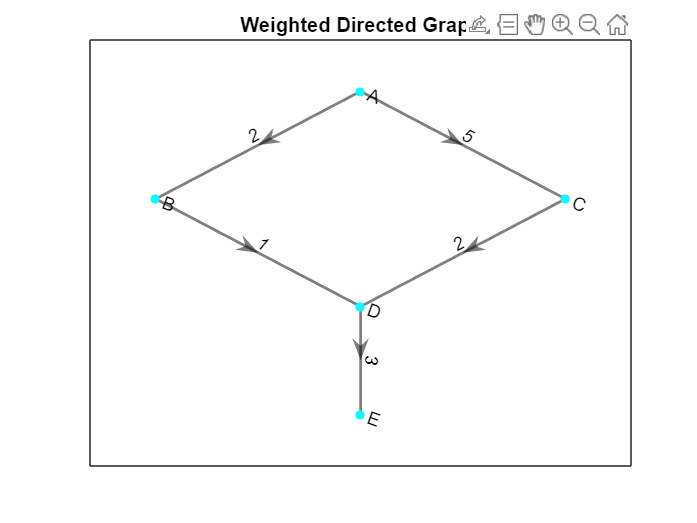

sources = [1 1 2 3 4];
targets = [2 3 4 4 5];
weights = [2 5 1 2 3];

G = digraph(sources, targets, weights);

nodeLabels = {'A' , 'B' , 'C' , 'D' , 'E'};

figure;
plot(G, 'Layout','layered' , 'NodeLabel',nodeLabels, ...
    'EdgeLabel',G.Edges.Weight,'LineWidth',1.5, ...
    'EdgeColor','black','ArrowSize',12, ...
    'NodeColor','cyan');
title('Weighted Directed Graph');



[startNode , endNode] = deal(1 ,5);
[path, pathLength] = shortestpath(G, startNode , endNode);

fprintf('Shortest path from %s to %s:\n' ,nodeLabels{startNode}, nodeLabels{endNode});

Shortest path from A to E:


disp(nodeLabels(path));

    {'A'}    {'B'}    {'D'}    {'E'}



fprintf('Total path length: %d\n' ,pathLength);

Total path length: 6
